# Integrator Lab: Solving First Order ODEs in MATLAB

This lab will teach you to numerically solve first order ODEs using a built in MATLAB integrator, `ode45`.  `ode45` is a good, general purpose tool for integrating first order equations (and first order systems). It is not always the right algorithm, but it is usually the right algorithm to try first.

You will learn how to use the `ode45` routine, how to interpolate between points, and how MATLAB handles data structures.

Opening the m-file lab2.m in the MATLAB editor, step through each part using cell mode to see the results. Compare the output with the PDF, which was generated from this m-file.

There are six exercises in this lab that are to be handed in at the end of the lab. Write your solutions in the template, including appropriate descriptions in each step. Save the .m file and submit it online using Quercus.

## Student Information

Student Name: Qingyuan Wu

Student Number: 1007001664

## Set up an inline function representation of an ODE and solve it

MATLAB has many built in routines for solving differential equations of the form

`y' = f(t,y)`

We will solve them using `ode45`, a high precision integrator. To do this, we will need to construct an inline function representation of `f`, an initial condition, and specify how far we want MATLAB to integrate the problem. Once we have set these, we pass the information to `ode45` to get the solution.

For a first example, we will solve the initial value problem

`y' = y, y(0) = 1`

which has as its answer `y = e^t`. 

% Set up the right hand side of the ODE as an inline function
f = @(t,y) y; 

% The initial conditions
t0 = 0;
y0 = 1;

% The time we will integrate until
t1 = 2;

soln = ode45(f, [t0, t1], y0);

## Examining the output

When we execute the `ode45`, it returns a data structure, stored in soln. We can see the pieces of the data structure with a display command:

disp(soln);

     solver: 'ode45'
    extdata: [1×1 struct]
          x: [1×11 double]
          y: [1×11 double]
      stats: [1×1 struct]
      idata: [1×1 struct]



## Understanding the components of the solution data structure

The most important elements of the data structure are stored in the `x` and `y` components of the structure; these are vectors. Vectors `x` and `y` contain the points at which the numerical approximation to the initial value problem has been computed. In other words, `y(j)` is the approximate value of the solution at `x(j)`.

**NOTE:** Even though we may be studying a problem like `u(t)` or `y(t)`, MATLAB will always use `x` for the independent variable and `y` for the dependent variable in the data structure.

Pieces of the data structure can be accessed using a period, as in C/C++ or Java. See the examples below:

% Display the values of |t| at which |y(t)| is approximated
fprintf(' Vector of t values: ');

 Vector of t values: 

disp(soln.x);

  Columns 1 through 4

         0    0.2000    0.4000    0.6000

  Columns 5 through 8

    0.8000    1.0000    1.2000    1.4000

  Columns 9 through 11

    1.6000    1.8000    2.0000



% Display the the corresponding approximations of |y(t)|
fprintf(' Vector of y values: ');

 Vector of y values: 

disp(soln.y);

  Columns 1 through 4

    1.0000    1.2214    1.4918    1.8221

  Columns 5 through 8

    2.2255    2.7183    3.3201    4.0552

  Columns 9 through 11

    4.9530    6.0496    7.3891




% Display the approximation of the solution at the 3rd point:
fprintf(' Third element of the vector of t values: %g\n',soln.x(3));

 Third element of the vector of t values: 0.4


fprintf(' Third element of the vector of y values: %g\n',soln.y(3));

 Third element of the vector of y values: 1.49182


## Visualizing and comparing the solution

We can now visualize the solution at the computed data points and compare with the exact solution.

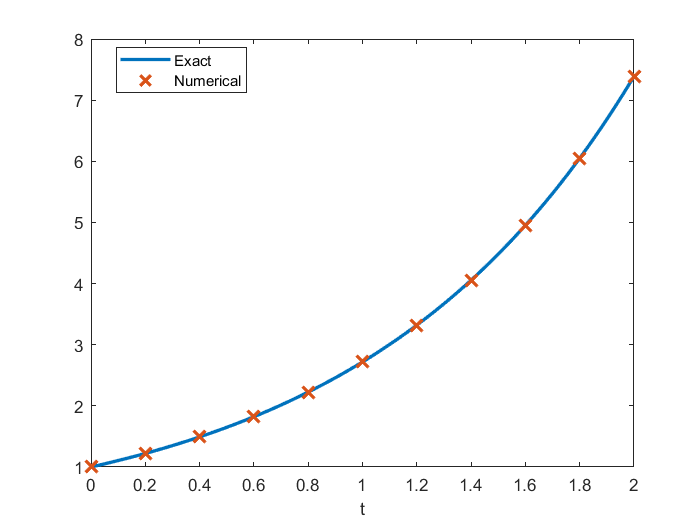

% Construct the exact solution
tt = linspace(0,2,50);
yy = exp(tt);

% Plot both on the same figure, plotting the approximation with x's
plot(tt, yy, soln.x, soln.y, 'x', 'MarkerSize',10, 'LineWidth', 2);
% NOTE: the MarkerSize and LineWidth are larger than their defaults of 6
% and 1, respectively.  This makes the print out more readable.

% Add a label to the axis and a legend
xlabel('t');
legend('Exact', 'Numerical','Location','Best');

## Exercise 1

Objective: Solve an initial value problem and plot both the numerical approximation and the corresponding exact solution.

Details: Solve the IVP

`y' = y tan t + sin t, y(0) = -1/2`

from `t = 0` to `t = pi`.

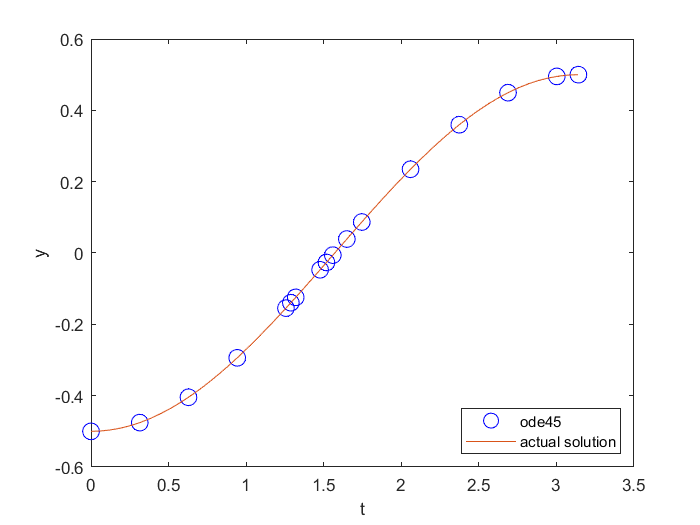

% Compute the exact solution (by hand), and plot both on the same figure
% for comparison, as above.
%
% Your submission should show the construction of the inline function, the
% use of ode45 to obtain the solution, a construction of the exact
% solution, and a plot showing both.  In the comments, include the exact
% solution.
%
% Label your axes and include a legend.

f = @(t, y) y*tan(t) + sin(t);
t0 = 0;
y0 = -1/2;
t1 = pi;

sol = ode45(f, [t0, t1], y0);

xactual = linspace(0, pi, 50);
% yactual = cos(2*xactual)./(-2*cos(xactual)); % this one's wrong for some
% reason

% exact solution: y = -cos(t)/2
yactual = -cos(xactual)/2;
plot(sol.x, sol.y, 'ob', 'MarkerSize', 10);
hold on;
plot(xactual, yactual);

legend("ode45", "actual solution", "location","southeast");
xlabel("t");
ylabel("y");
hold off;

## Computing an approximation at a specific point

As you should be able to see by examining `soln.x`, ode45 returns the solution at a number of points between `t0` and `t1`. But sometimes we want to know the solution at some intermediate point.

To obtain this value, we need to interpolate it in a consistent way. Fortunately, MATLAB provides a convenient function, `deval`, specifically for this.

% Compute the solution at t = .25:
deval(soln, .25)

ans = 1.2840


% Compute the solution at t = 1.6753:
fprintf(' Solution at 1.6753: %g\n', deval(soln, 1.6753));

 Solution at 1.6753: 5.3404



% Compute the solution at 10 grid points between .45 and 1.65:
tinterp = linspace(.45, 1.65, 10);
deval(soln, tinterp)

ans =     1.5683    1.7920    2.0476    2.3396    2.6734    3.0547    3.4903    3.9882    4.5570    5.2070



% Alternatively:
deval(soln, linspace(.45, 1.65, 10))

ans =     1.5683    1.7920    2.0476    2.3396    2.6734    3.0547    3.4903    3.9882    4.5570    5.2070


## Exercise 2

Objective: Interpolate a solution at a number of grid points

interpolate = deval(sol, linspace(2,3,10));
disp(interpolate);

  Columns 1 through 4

    0.2081    0.2572    0.3032    0.3454

  Columns 5 through 8

    0.3833    0.4166    0.4447    0.4673

  Columns 9 through 10

    0.4841    0.4950



% Details: For the solution you computed in exercise 1, use deval to
% compute the interpolated values at 10 grid points between 2 and 3.

## Errors, Step Sizes, and Tolerances

As you may have noticed, in contrast to the IODE software, at no point do we set a step size for our solution. Indeed, the step size is set adaptively to conform to a specified error tolerance. 

Roughly speaking, given the solution at `(t_j, y_j)`, `ode45` computes two approximations of the solution at `t_{j+1} = t_j + h`; one is of greater accuracy than the other. If the difference is below a specified tolerance, the step is accepted and we continue. Otherwise the step is rejected and the smaller step size, `h`, is used; it is often halved.

We can compute the global truncation error at each solution point, figure out the maximum error, and visualize this error (on a linear-log scale):

% Compute the exact solution
yexact = exp(soln.x);

% Compute the point-wise error; note the use of MATLAB's vectorization
err = abs(yexact - soln.y);

disp(err);

   1.0e-06 *

  Columns 1 through 4

         0    0.0152    0.0371    0.0679

  Columns 5 through 8

    0.1106    0.1688    0.2475    0.3526

  Columns 9 through 11

    0.4922    0.6764    0.9179




fprintf('maximum error: %g \n', max(err));

maximum error: 9.17923e-07 


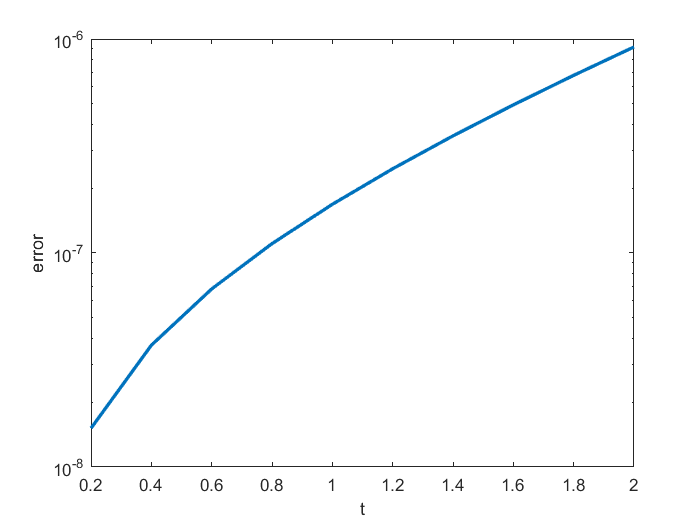


semilogy(soln.x, err, 'LineWidth', 2);
xlabel('t');
ylabel('error');
hold off;

## Exercise 3

Objective: Examine the error of a solution generated by `ode45`

% Details: For your solution to exercise 1, compute the point-wise error,
% identify the maximum value of the error, and visualize the error on a 
% linear-log plot (use semilogy to plot the log of the error vs. t).  
% Write in the comments where the error is largest, and give a brief 
% (1-2 sentences) explanation of why it is largest there.  Make sure to 
% label your axes.

% Exact solution:
yexact = -cos(sol.x)/2;
% compute error
error3 = abs(yexact - sol.y);
semilogy(sol.x, error3);

fprintf('maximum error: %g \n', max(error3));

maximum error: 1.8068e-05 


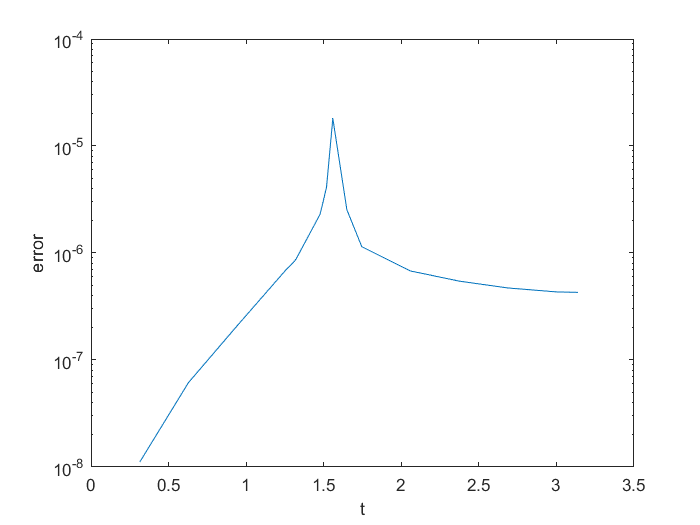


xlabel('t');
ylabel('error');

hold off;


% the error is the largest at around t=1.56s. It is the largest here since
% the solution has an inflection point. The rate of change of the
% derivative is at a maximum at t=1.5s.

## Exercise 4

Objective: Solve and visualize a nonlinear ode using ode45

Details: Solve the IVP

`y' = 1 / y^2 , y(1) = 1`


% from |t=1| to |t=10| using |ode45|.  Find the exact solution and compute
% the maximum point-wise error.  Then plot the approximate solution and the
% exact solution on the same axes.
% 
% Your solution should show the definition of the inline function,
% the computation of its solution in this interval, the computation of the
% exact solution at the computed grid points, the computation of the
% maximum error, and a plot of the exact and approximate solutions.
% Your axes should be appropriately labeled and include a legend.

f = @(t,y) 1/y.^2; % do t,y instead of y,t
t0 = 1;
y0 = 1;
t1 = 10;

sol4 = ode45(f, [t0, t1], y0);
sol4.x;
sol4.y;
plot(sol4.x, sol4.y);

% exact solution:
% y^2dy = dx
% y^3/3 = x + K
% y = (3x + C)^(1/3)
% initial condition: y(1) = 1 =>
% 1 = (3 + C)^(1/3)
% C = -2
% Exact solution: y = (3x-2)^(1/3)

y_exact_4 = (3.*sol4.x - 2).^(1/3);
hold on;
plot(sol4.x, y_exact_4);
xlabel("t");
ylabel("y");
legend("ode45", "exact solution");

% Compute maximum error:
error4 = abs(y_exact_4 - sol4.y);
max_error4 = max(error4);
fprintf('maximum error: %g \n', max_error4);

maximum error: 0.0017118 


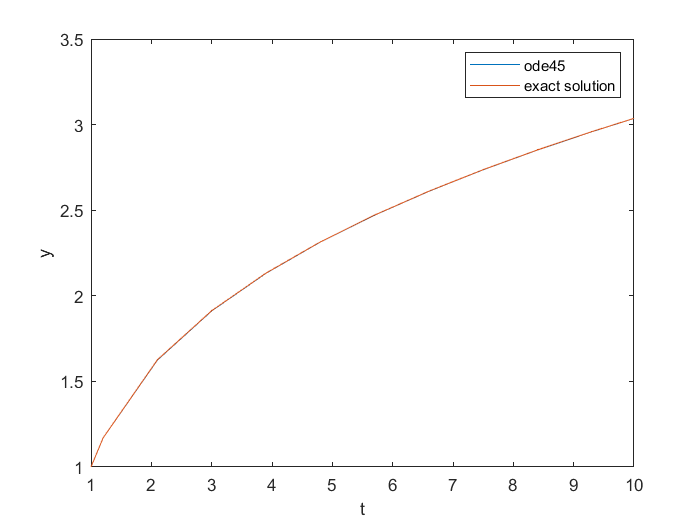


hold off;

## Exercise 5

Objective: Solve and visualize an ODE that cannot be solved by hand with `ode45`.

Details: Solve the IVP

`y' = 1 - t y / 2, y(0) = -1`

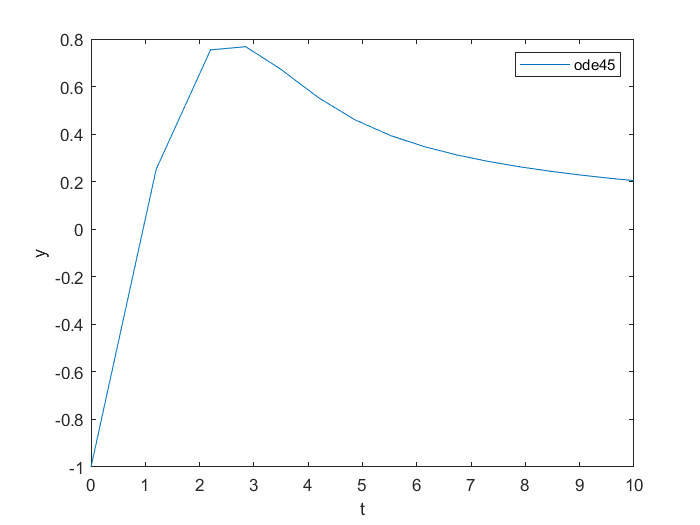

% from |t=0| to |t=10|.  
%
% Your solution should show you defining the inline function, computing
% the solution in this interval, and plotting it.
%
% Your axes should be appropriately labeled

f = @(y,t) 1- t*y/2;
y0 = -1;
t0 = 0;
t1 = 10;

sol5 = ode45(f, [t0, t1], y0);
plot(sol5.x, sol5.y);
xlabel("t");
ylabel("y");
legend("ode45");

hold off;

## Exercise 6 - When things go wrong

Objective: Solve an ode and explain the warning message

Details: Solve the IVP:

`y' = y^3 - t^2, y(0) = 1`

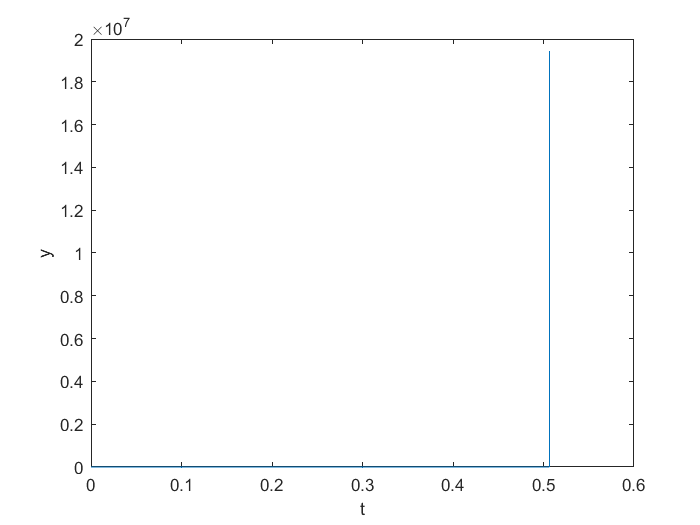

% from |t=0| to |t=1|.  
%
% Your solution should show you defining the inline function, and computing
% the solution in this interval.
% 
% If you try to plot the solution, you should find that the solution does
% not make it all the way to t = 1.
%
% In the comments explain why MATLAB generates the warning message that you
% may see, or fails to integrate all the way to t=1.  HINT: Try plotting
% the direction field for this with IODE.

f = @(t,y) y^3 - t^2;
t0 = 0;
y0 = 1;
t1 = 1;
sol6 = ode45(f, [t0,t1], y0);
plot(sol6.x, sol6.y);% the solution blows up to positive infinity at t=0.5.

xlabel("t");
ylabel("y");


% the warning is generated because the solution with initial value y(0)=1
% is only defined until t=0.5.
% There is an infinite discontinuity at t=0.5 (from looking at iode).
% The solution's slope becomes very large with very small timesteps as it
% approaches t=0.5. Therefore, ode45 displays a warning and can no longer
% compute the numerical solution.

